# Demodulation Error Test

## Clear Workspace

close all; clearvars; clc;

## Initialize Variables

N = 1e3; % set length of signal
A = 1; % pk-pkV of the component frequencies
sampleRate = 125e3; % Sets the rate that the NI-Boards sample in Hz
time = (0:(N-1)) / sampleRate; % Creates time vector
f1 = 10e3; % lowest frequency component Hz
f2 = 20e3; % mid frequency component Hz
f3 = 40e3; % highest frequency component Hz
k = 0:N-1; % vector of n points
tk = k/sampleRate; % time vector for xAxis

## Create signal

[signal, rawSignal] = createSine(A, f1, f2, f3, sampleRate, "bipolar", N, 20); % A, frq1, frq2, frq3, sampleRate, type, bufferForPreLoad, noise
signal = signal(1:N);
rawSignal = rawSignal(1:N);

## Plot Signal

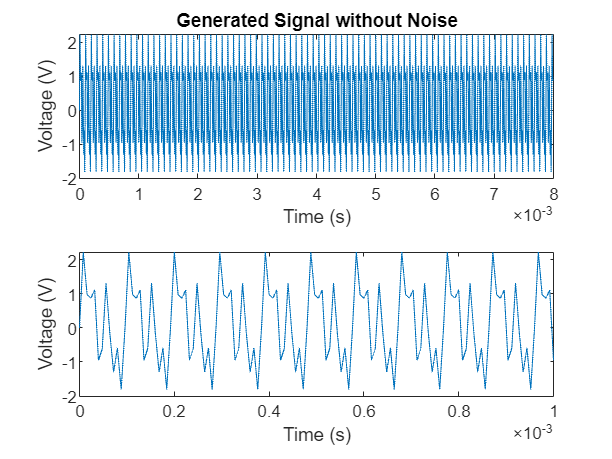

figure
subplot(2,1,1);
plot(time, rawSignal)
title('Generated Signal without Noise')
xlabel("Time (s)");
ylabel("Voltage (V)");
subplot(2,1,2);
plot(time, rawSignal)
xlabel("Time (s)");
ylabel("Voltage (V)");
xlim([0 1e-3])

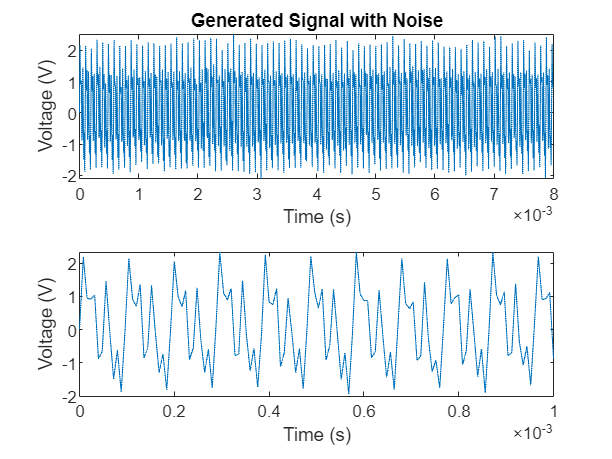


figure
subplot(2,1,1);
plot(time, signal)
title('Generated Signal with Noise')
xlabel("Time (s)");
ylabel("Voltage (V)");
subplot(2,1,2);
plot(time, signal)
xlabel("Time (s)");
ylabel("Voltage (V)");
xlim([0 1e-3])

## Frequency Demodulation

w01 = 2*pi*f1;    
w02 = 2*pi*f2;
w03 = 2*pi*f3;

% matrix containing the desired frequency component of the system
E1 = [sin(w01*tk)', cos(w01*tk)', ones(1, length(tk))']; 
E2 = [sin(w02*tk)', cos(w02*tk)', ones(1, length(tk))'];
E3 = [sin(w03*tk)', cos(w03*tk)', ones(1, length(tk))'];
Etot = [E1 E2 E3];

% inverse of E * s^t (pinv)
% phi1 = E(1)\signal; % gives alpha, beta and offset
% phi2 = E(2)\signal;
% phi3 = E(3)\signal;
phi_tot = pinv(Etot)*signal; %(:,1);

% seperate phi characteristics
alpha1 = phi_tot(1);
beta1 = phi_tot(2);
Cout1 = phi_tot(3);

alpha2 = phi_tot(4);
beta2 = phi_tot(5);
Cout2 = phi_tot(6);

alpha3 = phi_tot(7);
beta3 = phi_tot(8);
Cout3 = phi_tot(9);

% create the signal @wo
fsignal = Etot(:,1:3) * phi_tot(1:3,:) +  Etot(:,4:6) * phi_tot(4:6,:) + Etot(:,7:9) * phi_tot(7:9,:);
% + Etot(:,4:6) * phi_tot(4:6,:) + Etot(:,7:9) * phi_tot(7:9,:)

modF1 = Etot(:,1:3) * phi_tot(1:3,:);
modF2 = Etot(:,4:6) * phi_tot(4:6,:);
modF3 = Etot(:,7:9) * phi_tot(7:9,:);


## Plot Demodulated Signals

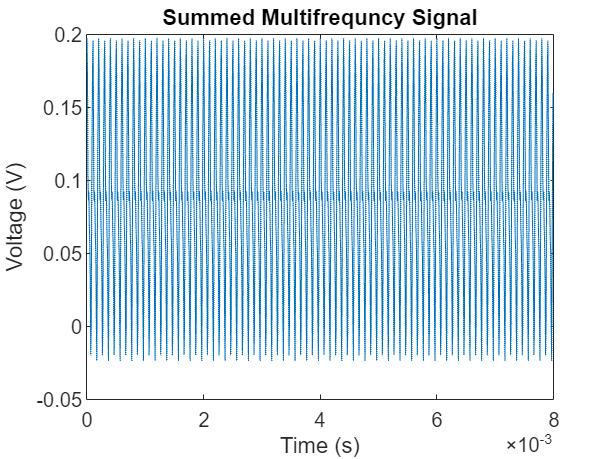

figure
plot(time,fsignal)
title("Summed Multifrequncy Signal")
xlabel("Time (s)");
ylabel("Voltage (V)");

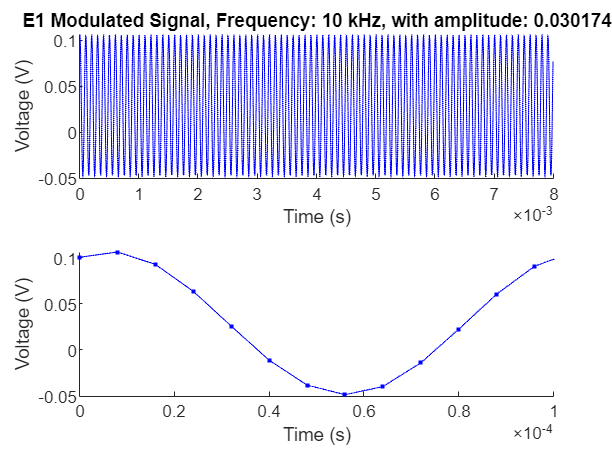


figure
subplot(2,1,1);
hold on;
plot(time, modF1, 'color', 'b')
title("E1 Modulated Signal, Frequency: " + f1/1e3 + " kHz, with amplitude: " + alpha1)
xlabel("Time (s)");
ylabel("Voltage (V)");
subplot(2,1,2);
hold on;
plot(time, modF1,'.-','color', 'b')
xlim([0 .0001])
xlabel("Time (s)");
ylabel("Voltage (V)");

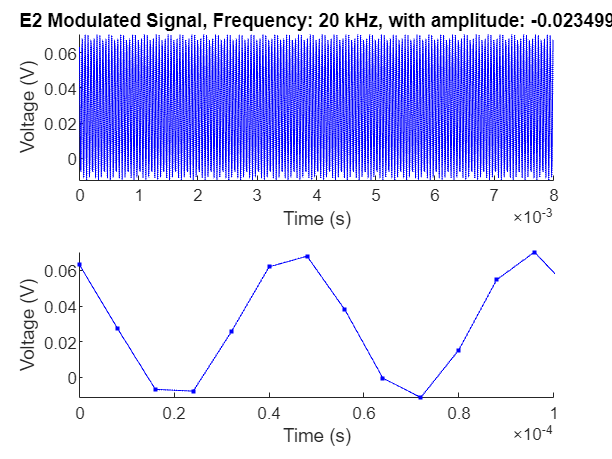


figure
subplot(2,1,1);
hold on;
plot(time, modF2, 'color', 'b')
title("E2 Modulated Signal, Frequency: " + f2/1e3 + " kHz, with amplitude: " + alpha2)
xlabel("Time (s)");
ylabel("Voltage (V)");
subplot(2,1,2);
hold on;
plot(time, modF2,'.-','color', 'b')
xlim([0 .0001])
xlabel("Time (s)");
ylabel("Voltage (V)");

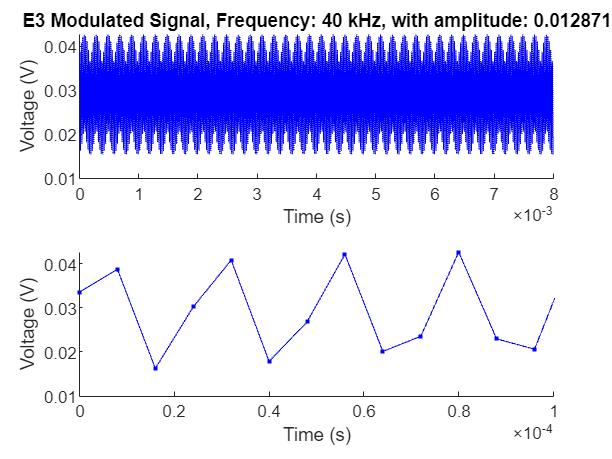


figure
subplot(2,1,1);
hold on;
plot(time, modF3, 'color', 'b')
title("E3 Modulated Signal, Frequency: " + f3/1e3 + " kHz, with amplitude: " + alpha3)
xlabel("Time (s)");
ylabel("Voltage (V)");
subplot(2,1,2);
hold on;
plot(time, modF3,'.-','color', 'b')
xlim([0 .0001])
xlabel("Time (s)");
ylabel("Voltage (V)");

## Sine Function

function [sine, rawWave] = createSine(A, frq1, frq2, frq3, sampleRate, type, bufferForPreLoad, noise)

timeStep = 1/sampleRate; % period of the sampling frequency
periods = 1/eval(gcd(sym([frq1 frq2 frq3]))); % calculates the length of the period for a periodic
t = (0:timeStep:periods-timeStep)'; % calculates the time vector from the period

if type == "bipolar"
    y = A*sin(2*pi*frq1*t) + A*sin(2*pi*frq2*t) + A*sin(2*pi*frq3*t); % calculates the signal along the time vector
elseif type == "unipolar"
    y = A*sin(2*pi*frq1*t) + A*sin(2*pi*frq2*t) + A*sin(2*pi*frq3*t) + A; % calculates the signal along the time vector
end

numCycles = ceil(bufferForPreLoad/length(y)); % calculate the number of cycles to make a full buffer for preloading
rawWave = repmat(y, numCycles, 1); % extends the data vector to match or execed the buffer length

sine = awgn(rawWave, noise, 'measured'); % adds white noise to the signal

end